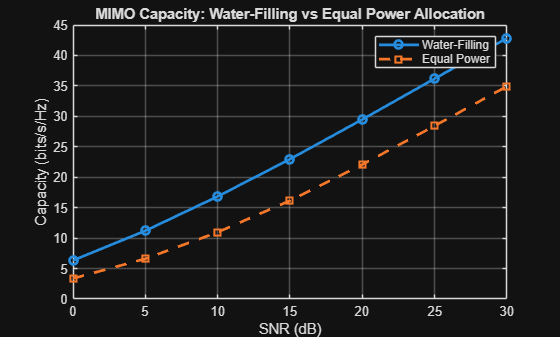

clc; clear; close all;

% Parameters
Nt = 4;              % Transmit antennas
Nr = 4;              % Receive antennas
EbN0_dB = 0:5:30;
N_iter = 1000;       % Channel realizations

capacity_wf = zeros(size(EbN0_dB));
capacity_equal = zeros(size(EbN0_dB));

for snr_idx = 1:length(EbN0_dB)
    
    SNR = 10^(EbN0_dB(snr_idx)/10);
    total_cap_wf = 0;
    total_cap_eq = 0;
    
    for iter = 1:N_iter
        
        % Rayleigh MIMO channel
        H = (randn(Nr,Nt) + 1j*randn(Nr,Nt))/sqrt(2);
        
        % SVD
        [~, S, ~] = svd(H);
        lambda = diag(S).^2;   % Eigenvalues
        
        % ================= Equal Power =================
        P_equal = SNR / Nt;
        cap_eq = sum(log2(1 + P_equal * lambda));
        
        % ================= Water-Filling =================
        N0 = 1;
        n = length(lambda);
        
        % Sort eigenvalues (descending)
        lambda_sorted = sort(lambda, 'descend');
        
        % Water-filling algorithm
        for k = 1:n
            mu = (SNR + sum(N0 ./ lambda_sorted(1:k))) / k;
            P = mu - N0 ./ lambda_sorted(1:k);
            
            if all(P >= 0)
                break;
            end
        end
        
        % Final power allocation
        P_alloc = max(0, mu - N0 ./ lambda);
        
        cap_wf = sum(log2(1 + P_alloc .* lambda));
        
        total_cap_wf = total_cap_wf + cap_wf;
        total_cap_eq = total_cap_eq + cap_eq;
        
    end
    
    capacity_wf(snr_idx) = total_cap_wf / N_iter;
    capacity_equal(snr_idx) = total_cap_eq / N_iter;
end

%% ================= Plot =================
figure;
plot(EbN0_dB, capacity_wf, 'o-', 'LineWidth', 2); hold on;
plot(EbN0_dB, capacity_equal, 's--', 'LineWidth', 2);

grid on;
xlabel('SNR (dB)');
ylabel('Capacity (bits/s/Hz)');
title('MIMO Capacity: Water-Filling vs Equal Power Allocation');
legend('Water-Filling','Equal Power');